# Unique iterations of Common graphs

## Boxplot

% Matlab has a fairly limited boxplot function
load carsmall
boxplot(MPG,Origin)
xlabel('All Vehicles')
ylabel('Miles per Gallon (MPG)')
title('Miles per Gallon for All Vehicles')

## Steps to build our own more versatile Boxplot

% 1. Load Data set
% 2. Create numerical elements needed for graphing
% 3. Use 'patch' and 'line' to build boxplot

## 1. Load Data set

% Load data set
load fisheriris.mat
% Create column names
% colnames = {'sepal_length', 'sepal_width', 'petal_length', 'petal_width'}; 
userData = meas;

## 2. Create numerical/statistical ingredients for boxplot

% Need boxplot ingredients
% 1. median
% 2. First Quartile
% 3. Third Quartile
% 4. Inter quartile range
% 5. Outlier limits
% 6. Outlier IDs

% % Set up the necessary elements

## Medians

medians = median(userData)

## Quartiles

% First quartile
fqrt = quantile(userData,0.25)
% Third quartile
tqrt = quantile(userData,0.75)

## Interquartile range

iqR = tqrt - fqrt

## Outlier limits

maxOLim = tqrt + (iqR * 1.5) % Tukey's Boxplot Whisker 
minOLim = fqrt - (iqR * 1.5)

maxWisk = max(userData);
minWisk = min(userData);

## Outlier IDs

% Create a LOGICAL matrix that contains placeholders for any values that should be considered outliers
outlierIDS = zeros(size(userData),'logical')
for oi = 1:size(outlierIDS,2)
    
    tmpCol = userData(:,oi); % Select a column
    tmpMin = minOLim(oi);    % Get the minimum boundary
    tmpMax = maxOLim(oi);    % Get the maximum boundary
    
    % Use conditionals to find any point outside bounds
    outlierIDS(:,oi) = tmpCol > tmpMax | tmpCol < tmpMin
    
end

sum(outlierIDS) % Check to make sure we found some outliers

## New Boxplot

% Loop through columns
clf
colorS = 'rgbk';
xAxisOffset = 0.25 % Jitter around x axis values
for boxI = 1:size(userData,2)
    
    % Create x-grid for patch
       % Counter clockwise starting in lower left corner
       % Center around integer
       % Four corners of box [bottom left , bottom right , top right , top left]
    xVars = [boxI - xAxisOffset boxI + xAxisOffset boxI + xAxisOffset boxI - xAxisOffset];
    % Create y-grid for patch
       % Must match order of x
       % 1. first quartile
       % 2. third quartile
       % Four corners of box [bottom left , bottom right , top right , top left]
    yVars =  [fqrt(boxI) fqrt(boxI) tqrt(boxI) tqrt(boxI)]
    
    % Put together in patch
    p = patch(xVars, yVars, colorS(boxI))
    p.FaceAlpha = 0.5; % Make it transparent - COOL!
    p.EdgeColor = 'none';
    % Add median
    hold on
    % To use the LINE function: 
       % First input = x values [start end]
       % Second input = y values [start end]
    line([boxI - xAxisOffset boxI + xAxisOffset] , [medians(boxI)  medians(boxI)], 'Color','k')
    % Add max and min lines
    % MAX
    line([boxI boxI] , [tqrt(boxI) maxWisk(boxI)], 'Color' , [0.5 0.5 0.5])
    % MIN
    line([boxI boxI] , [fqrt(boxI) minWisk(boxI)], 'Color', [0.5 0.5 0.5])
    
    % Add outliers
    plot(repmat(boxI,sum(outlierIDS(:,boxI)),1) , userData(outlierIDS(:,boxI),boxI),'k*')
 
end

figure;
boxplot(userData)

## Ribbon plot

figure;
% Fake data
x = 0.1:0.1:10

x =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000


y = sin(x)

y =     0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825   -0.9589


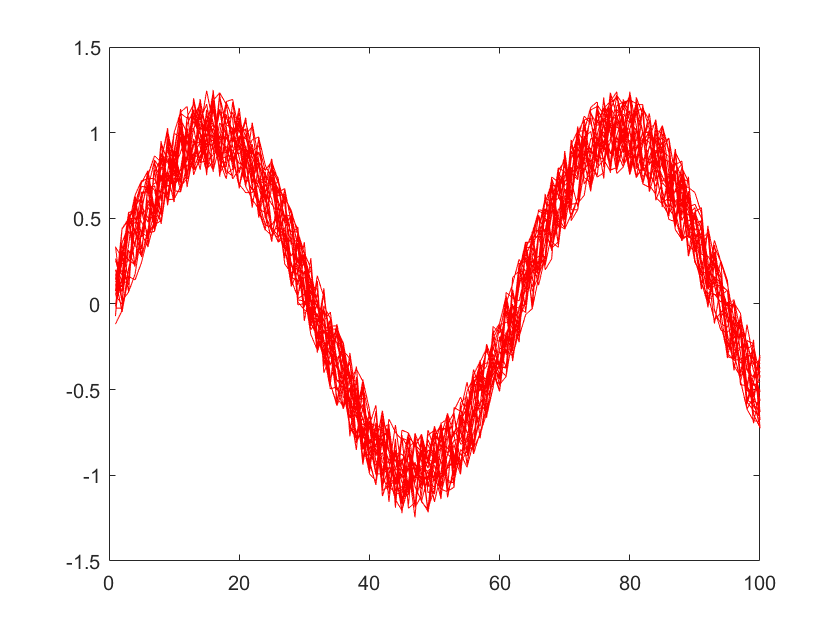


dataSet = transpose((((rand(25,length(y))*2)-1)/4) + repmat(y,25,1));
% Plot data
plot(dataSet,'r')

## Set up necessary plotting components

% 1. Mean
% 2. Upper Standard Deviation
% 3. Lower Standard Deviation

## Mean

% Derive mean for data sets
meanData = transpose(mean(dataSet,2))

meanData =     0.1042    0.1788    0.3605    0.4287    0.5022    0.5763    0.6070    0.7176    0.8025    0.7743    0.8853    0.8991    0.9620    0.9798    0.9670    1.0188    0.9565    0.9803    0.9349    0.9221    0.8701    0.8051    0.7411    0.6247    0.6452    0.5434    0.4780    0.3266    0.2306    0.1501    0.0144   -0.0979   -0.1505   -0.2515   -0.3416   -0.3956   -0.5387   -0.6218   -0.6904   -0.7995   -0.8396   -0.8560   -0.9118   -0.9661   -0.9996   -0.9563   -0.9620   -0.9379   -0.9908   -0.9131


## Standard Deviation

% Mean + SD: UPPER Bound
upperSD = meanData + transpose(std(dataSet,[],2))

upperSD =     0.2224    0.3251    0.5293    0.5850    0.6611    0.7273    0.7550    0.8725    0.9463    0.8925    1.0577    1.0358    1.1064    1.1052    1.0991    1.1687    1.1136    1.1186    1.0615    1.0655    0.9905    0.9395    0.8873    0.7393    0.8171    0.6648    0.6162    0.4906    0.3859    0.2850    0.1366    0.0351   -0.0073   -0.1169   -0.1763   -0.2672   -0.4047   -0.4826   -0.5291   -0.6772   -0.7054   -0.6982   -0.7651   -0.8314   -0.8478   -0.8209   -0.8087   -0.8072   -0.8471   -0.7877


% Mean - SD: LOWER Bound
lowerSD = meanData - transpose(std(dataSet,[],2))

lowerSD =    -0.0139    0.0324    0.1917    0.2724    0.3432    0.4253    0.4591    0.5627    0.6587    0.6562    0.7129    0.7623    0.8176    0.8544    0.8349    0.8689    0.7995    0.8420    0.8083    0.7787    0.7498    0.6707    0.5950    0.5100    0.4734    0.4221    0.3398    0.1627    0.0754    0.0152   -0.1078   -0.2309   -0.2937   -0.3860   -0.5069   -0.5240   -0.6727   -0.7609   -0.8516   -0.9218   -0.9737   -1.0138   -1.0585   -1.1008   -1.1513   -1.0918   -1.1154   -1.0685   -1.1346   -1.0385


## Construct plot

% Use 'patch' to create ribbon plot
% Remember to match x and y coordinates by wrapping around the entire object counter clockwise starting in lower left corner

% xVars: combine two elements - normal order x axis coordinates for lower bound AND flipped x axis coordinates for upper bound
lowerBoundX = 1:1:size(dataSet,2);
upperBoundX = fliplr(lowerBoundX);
xVars = [lowerBoundX , upperBoundX];

% yVars: almost similar to x
lowerBoundY = lowerSD

lowerBoundY =    -0.0139    0.0324    0.1917    0.2724    0.3432    0.4253    0.4591    0.5627    0.6587    0.6562    0.7129    0.7623    0.8176    0.8544    0.8349    0.8689    0.7995    0.8420    0.8083    0.7787    0.7498    0.6707    0.5950    0.5100    0.4734    0.4221    0.3398    0.1627    0.0754    0.0152   -0.1078   -0.2309   -0.2937   -0.3860   -0.5069   -0.5240   -0.6727   -0.7609   -0.8516   -0.9218   -0.9737   -1.0138   -1.0585   -1.1008   -1.1513   -1.0918   -1.1154   -1.0685   -1.1346   -1.0385


upperBoundY = fliplr(upperSD)

upperBoundY =    -0.3784   -0.3174   -0.2476   -0.0887   -0.0528    0.0452    0.1772    0.2981    0.3086    0.4882    0.5344    0.6452    0.7819    0.8188    0.8383    0.9737    1.0094    1.0283    1.0773    1.1526    1.1682    1.1380    1.1609    1.1790    1.1158    1.0906    1.0537    1.0241    0.9814    0.8623    0.7972    0.7537    0.6821    0.5834    0.4614    0.3841    0.3186    0.2021    0.0188   -0.0229   -0.1979   -0.2149   -0.3453   -0.3721   -0.4656   -0.5699   -0.6205   -0.7238   -0.6987   -0.7296


yVars = [lowerBoundY , upperBoundY]

yVars =    -0.0139    0.0324    0.1917    0.2724    0.3432    0.4253    0.4591    0.5627    0.6587    0.6562    0.7129    0.7623    0.8176    0.8544    0.8349    0.8689    0.7995    0.8420    0.8083    0.7787    0.7498    0.6707    0.5950    0.5100    0.4734    0.4221    0.3398    0.1627    0.0754    0.0152   -0.1078   -0.2309   -0.2937   -0.3860   -0.5069   -0.5240   -0.6727   -0.7609   -0.8516   -0.9218   -0.9737   -1.0138   -1.0585   -1.1008   -1.1513   -1.0918   -1.1154   -1.0685   -1.1346   -1.0385


## Patch ribbon plot

figure;
patch(xVars, yVars, 'r', 'FaceAlpha',0.3)

Error using patch
Vectors must be the same length.


% Add mean line
hold on
plot(meanData,'k','LineWidth',2)
